FILE_FILTER = '1.s2p';                 % 任务 1：滤波器 S2P (包含 S11, S21, S12, S22)
FILE_LOAD_GAMMA_L = '2.s1p';         % 任务 2：不匹配负载 S1P (Gamma_L)
FILE_MEASURED_GAMMA_IN = '3.s1p'; % 任务 3：测量 Gamma_in S1P

try
    Filter_S = sparameters(FILE_FILTER);
    F_Filter = Filter_S.Frequencies; % 频率向量 (Hz)
    
    % 提取 S21 和 S11 用于绘图
    S11_Filter = 20 * log10(abs(squeeze(Filter_S.Parameters(1, 1, :)))); % S11 (dB)
    S21_Filter = 20 * log10(abs(squeeze(Filter_S.Parameters(2, 1, :)))); % S21 (dB)
    S12_Filter = 20 * log10(abs(squeeze(Filter_S.Parameters(1, 2, :)))); % S12 (dB)
    S22_Filter = 20 * log10(abs(squeeze(Filter_S.Parameters(2, 2, :)))); % S22 (dB)catch ME
    warning('警告: 无法读取滤波器文件 %s，跳过此图绘制。错误信息: %s', FILE_FILTER, ME.message);
    S21_Filter = []; % 置空以便后续判断
end


% --- 读取负载 Gamma_L S1P 文件 (任务 2) ---
try
    Load_S = sparameters(FILE_LOAD_GAMMA_L);
    % Gamma_L 即 S11
    Gamma_L_dB = 20 * log10(abs(squeeze(Load_S.Parameters(1, 1, :))));
    F_Load = Load_S.Frequencies;
catch ME
    warning('警告: 无法读取负载文件 %s，跳过此图绘制。错误信息: %s', FILE_LOAD_GAMMA_L, ME.message);
    Gamma_L_dB = []; 
end


% --- 读取测量得到的 Gamma_in S1P 文件 (任务 3) ---
try
    Measured_Gamma_S = sparameters(FILE_MEASURED_GAMMA_IN);
    % 测量得到的 Gamma_in 即 S11
    Gamma_in_Measured_dB = 20 * log10(abs(squeeze(Measured_Gamma_S.Parameters(1, 1, :))));
    F_Measured = Measured_Gamma_S.Frequencies;
catch ME
    warning('警告: 无法读取测量结果文件 %s，跳过此图绘制。错误信息: %s', FILE_MEASURED_GAMMA_IN, ME.message);
    Gamma_in_Measured_dB = [];
end

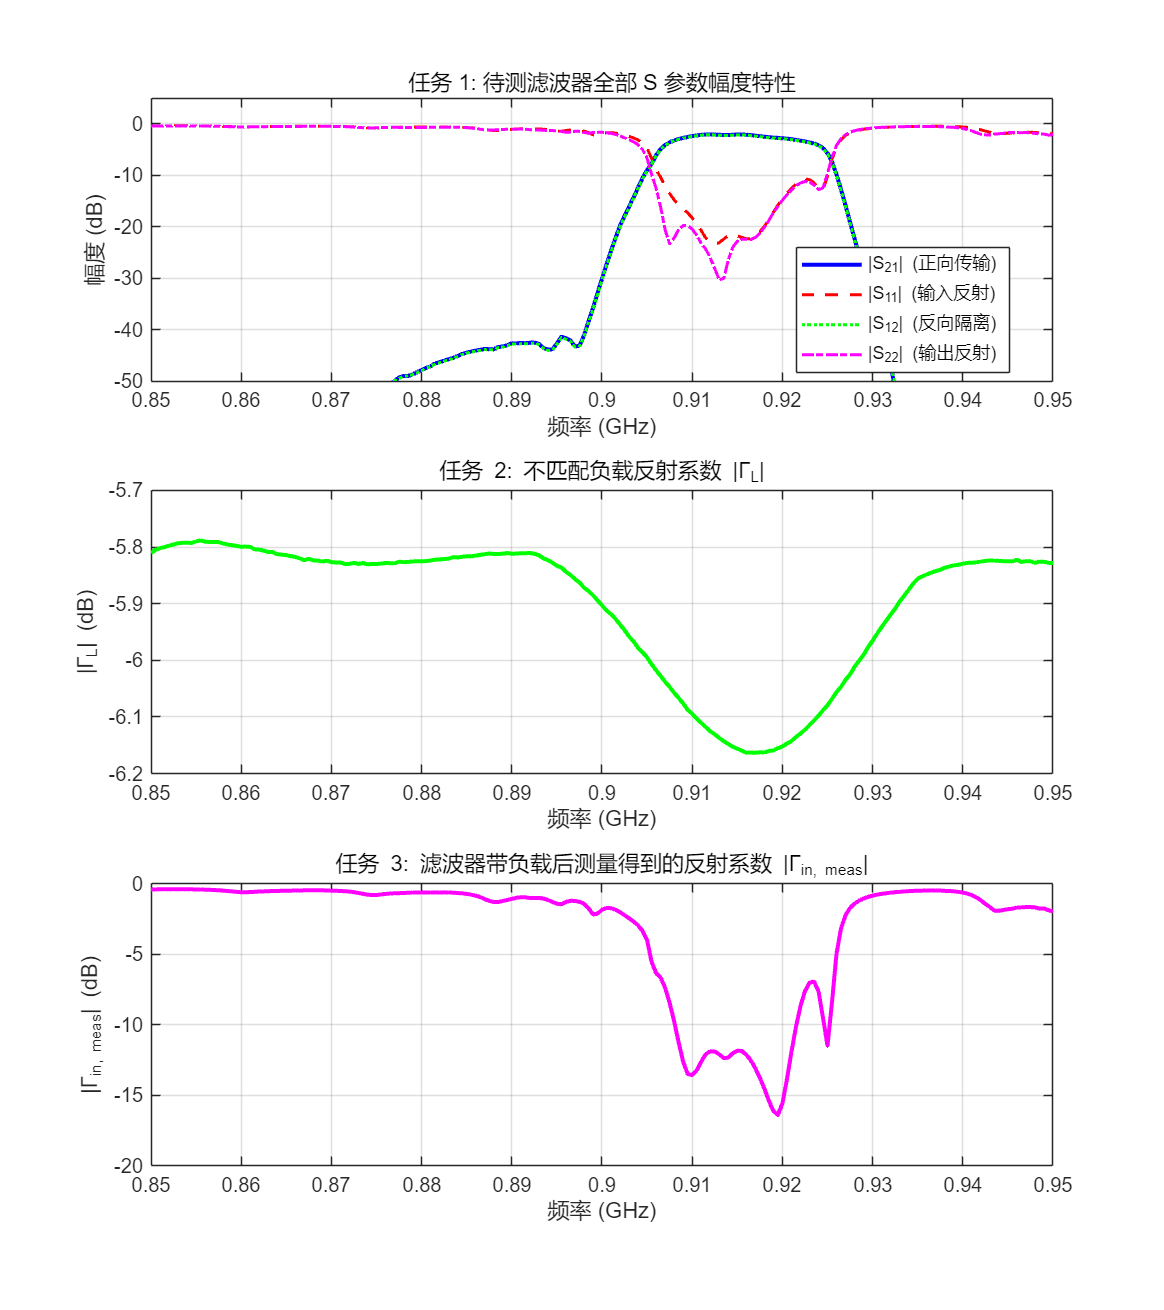


figure('Name', 'S参数实验测量结果概览');
set(gcf, 'Position', [100, 100, 800, 900]); % 调整窗口大小

% --- 图 1: 任务 1 滤波器 S 参数 (S21 和 S11) ---
if ~isempty(S21_Filter)
    subplot(3, 1, 1);
    F_GHz = F_Filter / 1e9;
    
    plot(F_GHz, S21_Filter, 'b', 'LineWidth', 2, 'DisplayName', '|S_{21}| (正向传输)');
    hold on;
    plot(F_GHz, S11_Filter, 'r--', 'LineWidth', 1.5, 'DisplayName', '|S_{11}| (输入反射)');
    plot(F_GHz, S12_Filter, 'g:', 'LineWidth', 1.5, 'DisplayName', '|S_{12}| (反向隔离)');
    plot(F_GHz, S22_Filter, 'm-.', 'LineWidth', 1.5, 'DisplayName', '|S_{22}| (输出反射)');
    hold off;
    
    grid on;
    title('任务 1: 待测滤波器全部 S 参数幅度特性');
    xlabel('频率 (GHz)');
    ylabel('幅度 (dB)');
    legend('Location', 'best');
    xlim([min(F_GHz) max(F_GHz)]);
    ylim([-50 5]); % 调整Y轴范围，通常 S参数不会超过0dB，以观察细节
end

% --- 图 2: 任务 2 不匹配负载 Gamma_L (S11) ---
if ~isempty(Gamma_L_dB)
    subplot(3, 1, 2);
    F_GHz = F_Load / 1e9;
    
    plot(F_GHz, Gamma_L_dB, 'g', 'LineWidth', 2);
    
    grid on;
    title('任务 2: 不匹配负载反射系数 |\Gamma_L|');
    xlabel('频率 (GHz)');
    ylabel('|\Gamma_L| (dB)');
    xlim([min(F_GHz) max(F_GHz)]);
end

% --- 图 3: 任务 3 测量得到的 Gamma_in (S11) ---
if ~isempty(Gamma_in_Measured_dB)
    subplot(3, 1, 3);
    F_GHz = F_Measured / 1e9;
    
    plot(F_GHz, Gamma_in_Measured_dB, 'm', 'LineWidth', 2);
    
    grid on;
    title('任务 3: 滤波器带负载后测量得到的反射系数 |\Gamma_{in, meas}|');
    xlabel('频率 (GHz)');
    ylabel('|\Gamma_{in, meas}| (dB)');
    xlim([min(F_GHz) max(F_GHz)]);
end

FILE_FILTER = '1.s2p';                 % 任务 1 测量的滤波器 S2P 文件
FILE_LOAD_GAMMA_L = '2.s1p';         % 任务 2 测量的负载反射系数 Gamma_L 文件
FILE_MEASURED_GAMMA_IN = '3.s1p'; % 任务 3 测量的实际 Gamma_in 文件

% =========================================================================
% 步骤 2: 读取 S 参数数据
% =========================================================================

% 读取滤波器 S2P 文件
try
    Filter_S = sparameters(FILE_FILTER);
catch ME
    error('无法读取滤波器文件 %s。请检查文件名是否正确且 RF Toolbox 已安装。', FILE_FILTER);
end


% 提取滤波器 S 参数
% S_params.Parameters 是一个 2x2xN 的矩阵，N 是频率点数
S11 = squeeze(Filter_S.Parameters(1, 1, :));
S12 = squeeze(Filter_S.Parameters(1, 2, :));
S21 = squeeze(Filter_S.Parameters(2, 1, :));
S22 = squeeze(Filter_S.Parameters(2, 2, :));
F_Filter = Filter_S.Frequencies; % 频率向量 (Hz)

% 读取负载 Gamma_L (S1P 文件中的 S11)
try
    Load_S = sparameters(FILE_LOAD_GAMMA_L);
catch ME
    error('无法读取负载文件 %s。请检查文件名是否正确。', FILE_LOAD_GAMMA_L);
end

Gamma_L = squeeze(Load_S.Parameters(1, 1, :)); % Gamma_L = S11 of the load

% 读取测量得到的 Gamma_in (S1P 文件中的 S11)
try
    Measured_Gamma_S = sparameters(FILE_MEASURED_GAMMA_IN);
catch ME
    error('无法读取测量结果文件 %s。请检查文件名是否正确。', FILE_MEASURED_GAMMA_IN);
end

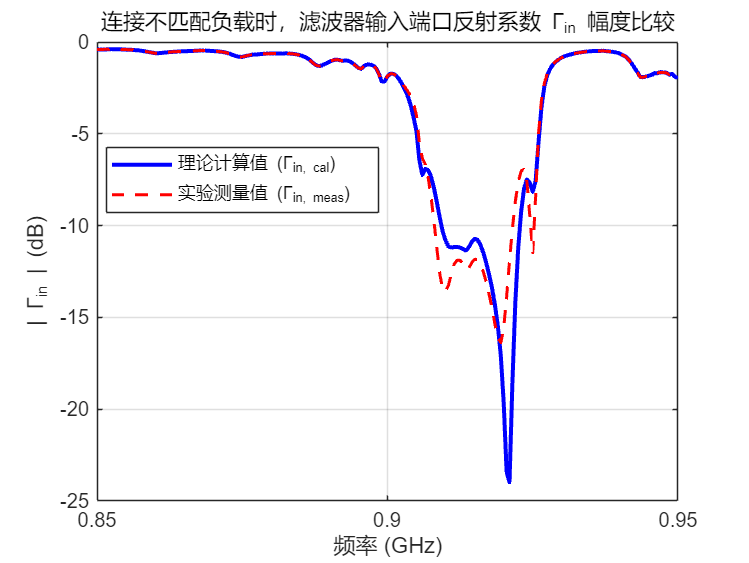

Gamma_in_Measured = squeeze(Measured_Gamma_S.Parameters(1, 1, :));
F_Measured = Measured_Gamma_S.Frequencies;


% 检查频率点是否匹配 (重要步骤)
if ~all(size(F_Filter) == size(F_Measured)) || any(F_Filter ~= F_Measured)
    warning('警告: 三个文件的频率点可能不完全匹配。为了计算准确，建议在矢网仪上使用相同的频率设置。');
    % 为了进行计算，这里假设 Gamma_L 和 Gamma_in_Measured 的频率向量与 Filter_S 相同
    % 在实际操作中，如果频率不匹配，需要进行插值 (interp1)，但在此简化处理。
end

% =========================================================================
% 步骤 3: 理论计算 Gamma_in (反射系数)
% =========================================================================
% 公式: Gamma_in = S11 + (S12 * S21 * Gamma_L) / (1 - S22 * Gamma_L)

Gamma_in_Calculated = S11 + (S12 .* S21 .* Gamma_L) ./ (1 - S22 .* Gamma_L);


% =========================================================================
% 步骤 4: 转换幅度为对数单位 (dB)
% =========================================================================

% 计算幅度的 dB 值
Gamma_in_Calculated_dB = 20 * log10(abs(Gamma_in_Calculated));
Gamma_in_Measured_dB = 20 * log10(abs(Gamma_in_Measured));


% =========================================================================
% 步骤 5: 绘图比较
% =========================================================================
figure;

% 频率单位转换为 GHz
F_GHz = F_Filter / 1e9;

plot(F_GHz, Gamma_in_Calculated_dB, 'b-', 'LineWidth', 2);
hold on;
plot(F_GHz, Gamma_in_Measured_dB, 'r--', 'LineWidth', 1.5);
hold off;

grid on;
title('连接不匹配负载时，滤波器输入端口反射系数 \Gamma_{in} 幅度比较');
xlabel('频率 (GHz)');
ylabel('| \Gamma_{in} | (dB)');
legend('理论计算值 (\Gamma_{in, cal})', '实验测量值 (\Gamma_{in, meas})', 'Location', 'best');
xlim([min(F_GHz) max(F_GHz)]); % 确保 X 轴范围与实验设置一致